# Analysis of Covariance (ANCOVA)

clear; clc; 
cd('/Users/duncan/Documents/GitHub/Advanced-Biomedical-Experimental-Design-and-Statistics/Mixed Analysis of Variance (MANOVA)')

## Setting up the Data

calculus = [10,30,50,60,80,100];
highschool = [20,45,40,60,55,80];
section = [repelem(1, 3), repelem(2, 3)];
sbj = 1:6; 
mydata = table(sbj', section', calculus', highschool', 'VariableNames', {'sbj', 'sec', 'calc', 'hs'})

mydata = 6×4 table
    sbj    sec    calc    hs
    ___    ___    ____    __

     1      1      10     20
     2      1      30     45
     3      1      50     40
     4      2      60     60
     5      2      80     55
     6      2     100     80


## Plot Data

% we'll see 
m1 = fitlm(mydata, 'calc ~ sec')

m1 = Linear regression model:
    calc ~ 1 + sec

Estimated Coefficients:
                   Estimate     SE       tStat     pValue 
                   ________    _____    _______    _______

    (Intercept)      -20       25.82    -0.7746    0.48182
    sec               50       16.33     3.0619    0.03759


Number of observations: 6, Error degrees of freedom: 4
Root Mean Squared Error: 20
R-squared: 0.701,  Adjusted R-Squared: 0.626
F-statistic vs. constant model: 9.38, p-value = 0.0376

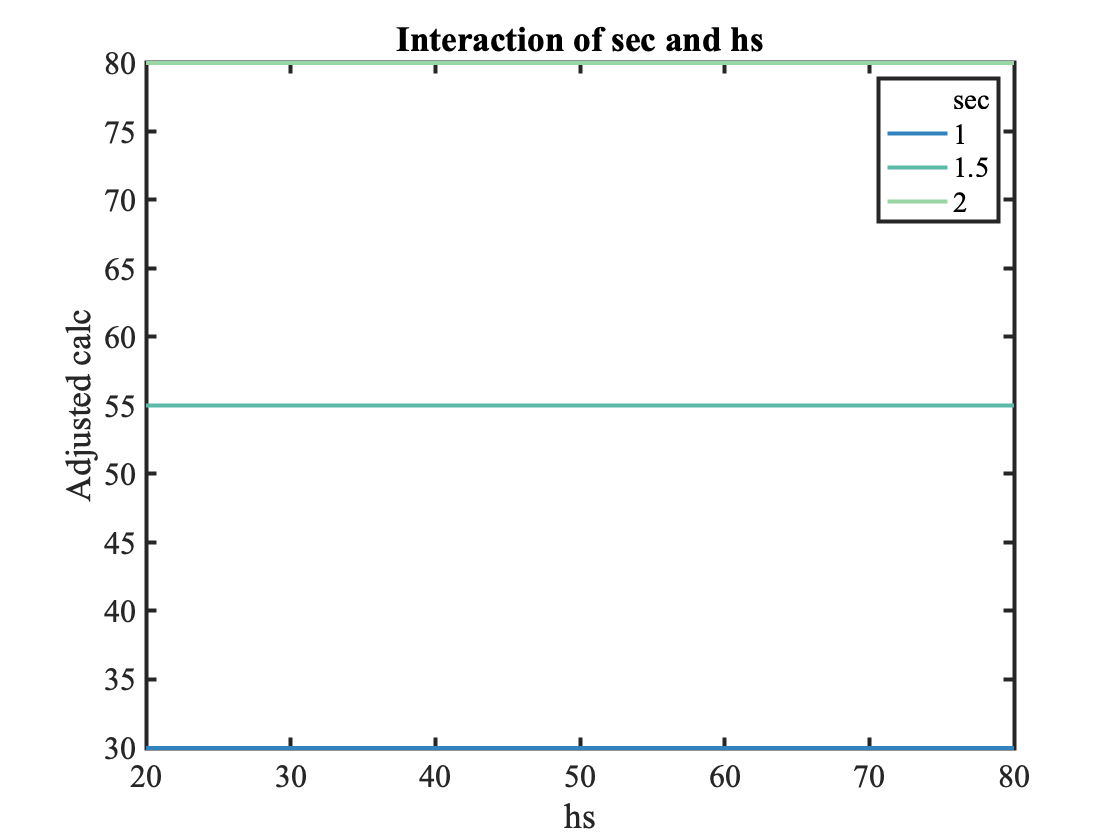

m1.plotInteraction('sec', 'hs', 'predictions') % UGLY 

## ANOVA (no covariates)

anova(m1)

ans = 2×5 table
             SumSq    DF    MeanSq      F      pValue 
             _____    __    ______    _____    _______

    sec      3750     1      3750     9.375    0.03759
    Error    1600     4       400                     


## ANCOVA (control for covariates)

m2 = fitlm(mydata, 'calc ~ sec + hs')

m2 = Linear regression model:
    calc ~ 1 + sec + hs

Estimated Coefficients:
                   Estimate      SE        tStat     pValue 
                   ________    _______    _______    _______

    (Intercept)    -25.714      19.726    -1.3036     0.2834
    sec             15.714      21.125    0.74388    0.51091
    hs              1.1429     0.57143          2    0.13933


Number of observations: 6, Error degrees of freedom: 3
Root Mean Squared Error: 15.1
R-squared: 0.872,  Adjusted R-Squared: 0.786
F-statistic vs. constant model: 10.2, p-value = 0.0459

anova(m2)

ans = 3×5 table
             SumSq     DF    MeanSq       F       pValue 
             ______    __    ______    _______    _______

    sec      126.48    1     126.48    0.55335    0.51091
    hs       914.29    1     914.29          4    0.13933
    Error    685.71    3     228.57                      


## ANCOVA - Homogeneity of Regression Slopes

m3 = fitlm(mydata, 'calc ~ sec * hs')

m3 = Linear regression model:
    calc ~ 1 + sec*hs

Estimated Coefficients:
                   Estimate       SE        tStat       pValue 
                   _________    ______    __________    _______

    (Intercept)      -25.714     97.52      -0.26368    0.81671
    sec               15.714    74.615       0.21061     0.8527
    hs                1.1429    2.2131        0.5164      0.657
    sec:hs         1.122e-15    1.3997    8.0159e-16          1


Number of observations: 6, Error degrees of freedom: 2
Root Mean Squared Error: 18.5
R-squared: 0.872,  Adjusted R-Squared: 0.68
F-statistic vs. constant model: 4.53, p-value = 0.186

anova(m3)

ans = 4×5 table
                SumSq      DF     MeanSq          F         pValue 
              _________    __    _________    __________    _______

    sec          126.48    1        126.48        0.3689    0.60538
    hs           914.29    1        914.29        2.6667    0.24407
    sec:hs    2.203e-28    1     2.203e-28    6.4255e-31          1
    Error        685.71    2        342.86                         


## ANCOVA - Normality of Residuals

[h,p,w] = swtest(m3.Residuals.Raw)

h = logical
   0


p = 0.6020

w = 0.9328

## ANCOVA - Homogeneity of Variance

% can't find an easy function on file exchange 

## ADJUSTED Mean Comparisons, Outputting Adjusted Means, Outputting Sample Effect Size, Power Analysis on ANCOVA 

% not sure 

## Local functions

function [H, pValue, W] = swtest(x, alpha)
% From https://www.mathworks.com/matlabcentral/fileexchange/13964-shapiro-wilk-and-shapiro-francia-normality-tests
%SWTEST Shapiro-Wilk parametric hypothesis test of composite normality.
%   [H, pValue, SWstatistic] = SWTEST(X, ALPHA) performs the
%   Shapiro-Wilk test to determine if the null hypothesis of
%   composite normality is a reasonable assumption regarding the
%   population distribution of a random sample X. The desired significance 
%   level, ALPHA, is an optional scalar input (default = 0.05).
%
%   The Shapiro-Wilk and Shapiro-Francia null hypothesis is: 
%   "X is normal with unspecified mean and variance."
%
%   This is an omnibus test, and is generally considered relatively
%   powerful against a variety of alternatives.
%   Shapiro-Wilk test is better than the Shapiro-Francia test for
%   Platykurtic sample. Conversely, Shapiro-Francia test is better than the
%   Shapiro-Wilk test for Leptokurtic samples.
%
%   When the series 'X' is Leptokurtic, SWTEST performs the Shapiro-Francia
%   test, else (series 'X' is Platykurtic) SWTEST performs the
%   Shapiro-Wilk test.
% 
%    [H, pValue, SWstatistic] = SWTEST(X, ALPHA)
%
% Inputs:
%   X - a vector of deviates from an unknown distribution. The observation
%     number must exceed 3 and less than 5000.
%
% Optional inputs:
%   ALPHA - The significance level for the test (default = 0.05).
%  
% Outputs:
%  SWstatistic - The test statistic (non normalized).
%
%   pValue - is the p-value, or the probability of observing the given
%     result by chance given that the null hypothesis is true. Small values
%     of pValue cast doubt on the validity of the null hypothesis.
%
%     H = 0 => Do not reject the null hypothesis at significance level ALPHA.
%     H = 1 => Reject the null hypothesis at significance level ALPHA.
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                Copyright (c) 17 March 2009 by Ahmed Ben Saïda          %
%                 Department of Finance, IHEC Sousse - Tunisia           %
%                       Email: ahmedbensaida@yahoo.com                   %
%                    $ Revision 3.0 $ Date: 18 Juin 2014 $               %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% References:
%
% - Royston P. "Remark AS R94", Applied Statistics (1995), Vol. 44,
%   No. 4, pp. 547-551.
%   AS R94 -- calculates Shapiro-Wilk normality test and P-value
%   for sample sizes 3 <= n <= 5000. Handles censored or uncensored data.
%   Corrects AS 181, which was found to be inaccurate for n > 50.
%   Subroutine can be found at: http://lib.stat.cmu.edu/apstat/R94
%
% - Royston P. "A pocket-calculator algorithm for the Shapiro-Francia test
%   for non-normality: An application to medicine", Statistics in Medecine
%   (1993a), Vol. 12, pp. 181-184.
%
% - Royston P. "A Toolkit for Testing Non-Normality in Complete and
%   Censored Samples", Journal of the Royal Statistical Society Series D
%   (1993b), Vol. 42, No. 1, pp. 37-43.
%
% - Royston P. "Approximating the Shapiro-Wilk W-test for non-normality",
%   Statistics and Computing (1992), Vol. 2, pp. 117-119.
%
% - Royston P. "An Extension of Shapiro and Wilk's W Test for Normality
%   to Large Samples", Journal of the Royal Statistical Society Series C
%   (1982a), Vol. 31, No. 2, pp. 115-124.
%
%
% Ensure the sample data is a VECTOR.
%
if numel(x) == length(x)
    x  =  x(:);               % Ensure a column vector.
else
    error(' Input sample ''X'' must be a vector.');
end
%
% Remove missing observations indicated by NaN's and check sample size.
%
x  =  x(~isnan(x));
if length(x) < 3
   error(' Sample vector ''X'' must have at least 3 valid observations.');
end
if length(x) > 5000
    warning('Shapiro-Wilk test might be inaccurate due to large sample size ( > 5000).');
end
%
% Ensure the significance level, ALPHA, is a 
% scalar, and set default if necessary.
%
if (nargin >= 2) && ~isempty(alpha)
   if ~isscalar(alpha)
      error(' Significance level ''Alpha'' must be a scalar.');
   end
   if (alpha <= 0 || alpha >= 1)
      error(' Significance level ''Alpha'' must be between 0 and 1.'); 
   end
else
   alpha  =  0.05;
end
% First, calculate the a's for weights as a function of the m's
% See Royston (1992, p. 117) and Royston (1993b, p. 38) for details
% in the approximation.
x       =   sort(x); % Sort the vector X in ascending order.
n       =   length(x);
mtilde  =   norminv(((1:n)' - 3/8) / (n + 1/4));
weights =   zeros(n,1); % Preallocate the weights.
if kurtosis(x) > 3
    
    % The Shapiro-Francia test is better for leptokurtic samples.
    
    weights =   1/sqrt(mtilde'*mtilde) * mtilde;
    %
    % The Shapiro-Francia statistic W' is calculated to avoid excessive
    % rounding errors for W' close to 1 (a potential problem in very
    % large samples).
    %
    W   =   (weights' * x)^2 / ((x - mean(x))' * (x - mean(x)));
    % Royston (1993a, p. 183):
    nu      =   log(n);
    u1      =   log(nu) - nu;
    u2      =   log(nu) + 2/nu;
    mu      =   -1.2725 + (1.0521 * u1);
    sigma   =   1.0308 - (0.26758 * u2);
    newSFstatistic  =   log(1 - W);
    %
    % Compute the normalized Shapiro-Francia statistic and its p-value.
    %
    NormalSFstatistic =   (newSFstatistic - mu) / sigma;
    
    % Computes the p-value, Royston (1993a, p. 183).
    pValue   =   1 - normcdf(NormalSFstatistic, 0, 1);
    
else
    
    % The Shapiro-Wilk test is better for platykurtic samples.
    c    =   1/sqrt(mtilde'*mtilde) * mtilde;
    u    =   1/sqrt(n);
    % Royston (1992, p. 117) and Royston (1993b, p. 38):
    PolyCoef_1   =   [-2.706056 , 4.434685 , -2.071190 , -0.147981 , 0.221157 , c(n)];
    PolyCoef_2   =   [-3.582633 , 5.682633 , -1.752461 , -0.293762 , 0.042981 , c(n-1)];
    % Royston (1992, p. 118) and Royston (1993b, p. 40, Table 1)
    PolyCoef_3   =   [-0.0006714 , 0.0250540 , -0.39978 , 0.54400];
    PolyCoef_4   =   [-0.0020322 , 0.0627670 , -0.77857 , 1.38220];
    PolyCoef_5   =   [0.00389150 , -0.083751 , -0.31082 , -1.5861];
    PolyCoef_6   =   [0.00303020 , -0.082676 , -0.48030];
    PolyCoef_7   =   [0.459 , -2.273];
    weights(n)   =   polyval(PolyCoef_1 , u);
    weights(1)   =   -weights(n);
    
    if n > 5
        weights(n-1) =   polyval(PolyCoef_2 , u);
        weights(2)   =   -weights(n-1);
    
        count  =   3;
        phi    =   (mtilde'*mtilde - 2 * mtilde(n)^2 - 2 * mtilde(n-1)^2) / ...
                (1 - 2 * weights(n)^2 - 2 * weights(n-1)^2);
    else
        count  =   2;
        phi    =   (mtilde'*mtilde - 2 * mtilde(n)^2) / ...
                (1 - 2 * weights(n)^2);
    end
        
    % Special attention when n = 3 (this is a special case).
    if n == 3
        % Royston (1992, p. 117)
        weights(1)  =   1/sqrt(2);
        weights(n)  =   -weights(1);
        phi = 1;
    end
    %
    % The vector 'WEIGHTS' obtained next corresponds to the same coefficients
    % listed by Shapiro-Wilk in their original test for small samples.
    %
    weights(count : n-count+1)  =  mtilde(count : n-count+1) / sqrt(phi);
    %
    % The Shapiro-Wilk statistic W is calculated to avoid excessive rounding
    % errors for W close to 1 (a potential problem in very large samples).
    %
    W   =   (weights' * x) ^2 / ((x - mean(x))' * (x - mean(x)));
    %
    % Calculate the normalized W and its significance level (exact for
    % n = 3). Royston (1992, p. 118) and Royston (1993b, p. 40, Table 1).
    %
    newn    =   log(n);
    if (n >= 4) && (n <= 11)
    
        mu      =   polyval(PolyCoef_3 , n);
        sigma   =   exp(polyval(PolyCoef_4 , n));    
        gam     =   polyval(PolyCoef_7 , n);
    
        newSWstatistic  =   -log(gam-log(1-W));
    
    elseif n > 11
    
        mu      =   polyval(PolyCoef_5 , newn);
        sigma   =   exp(polyval(PolyCoef_6 , newn));
    
        newSWstatistic  =   log(1 - W);
    
    elseif n == 3
        mu      =   0;
        sigma   =   1;
        newSWstatistic  =   0;
    end
    %
    % Compute the normalized Shapiro-Wilk statistic and its p-value.
    %
    NormalSWstatistic   =   (newSWstatistic - mu) / sigma;
    
    % NormalSWstatistic is referred to the upper tail of N(0,1),
    % Royston (1992, p. 119).
    pValue       =   1 - normcdf(NormalSWstatistic, 0, 1);
    
    % Special attention when n = 3 (this is a special case).
    if n == 3
        pValue  =   6/pi * (asin(sqrt(W)) - asin(sqrt(3/4)));
        % Royston (1982a, p. 121)
    end
    
end
%
% To maintain consistency with existing Statistics Toolbox hypothesis
% tests, returning 'H = 0' implies that we 'Do not reject the null 
% hypothesis at the significance level of alpha' and 'H = 1' implies 
% that we 'Reject the null hypothesis at significance level of alpha.'
%
H  = (alpha >= pValue);
end

